# Lab 3 - Convolution and filtering

## Question 1

### 1a) Load the signal xs in dataset3.mat

load dataset3

### 1b) Plot the amplitude and phase spectrum of the signal xs 

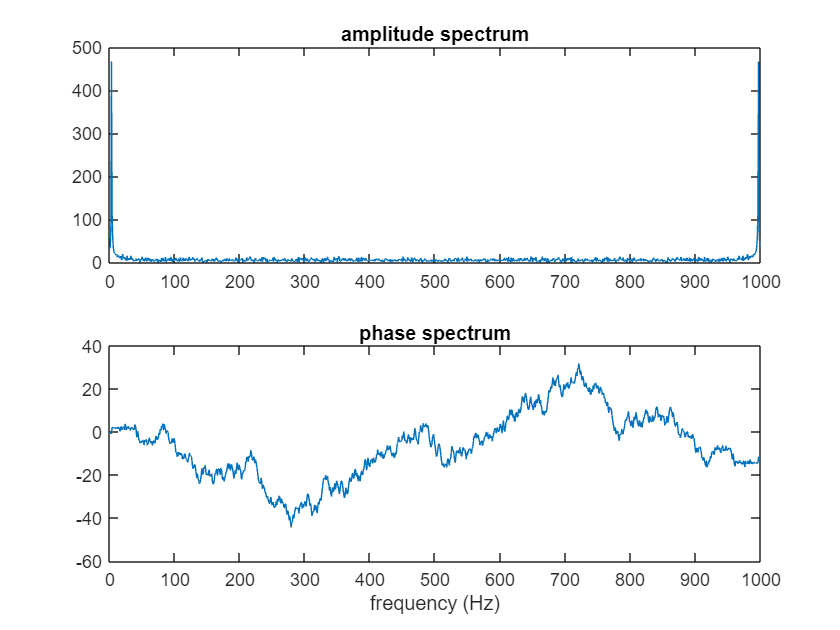

fs=1000; % sampling frequency
% Use your code from the previous lab to generate the spectra

Xs = fft(xs); %perform fft
f = (0:length(Xs)-1)*fs/length(Xs); % frequency vector --> NECESSARY TO PLOT SIGNAL VERSUS FREQUENCIES!

figure%('Name', 'Q1 b) Phase and Amplitude of xs')
subplot(2,1,1)
plot(f,abs(Xs)) %-> Abs to find modulus so amplitude
title('amplitude spectrum')
subplot(2,1,2)
plot(f,unwrap(angle(Xs))) %-> angle to find argument so sphase
title('phase spectrum')
xlabel('frequency (Hz)')

or do using own written plotfft function

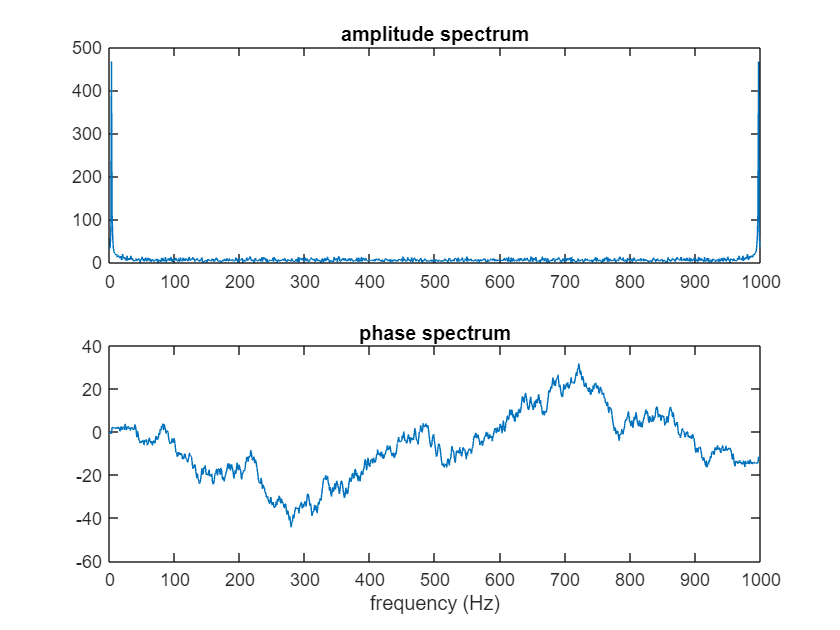

plotfft(xs,fs);

### 1c)					

#### What is the freqz

#### t frequency in the amplitude spectrum? 

%find dominant frequencies
[values,idx] = sort(abs(Xs),'descend')

values =   467.0474  467.0474  113.8081  113.8081   67.9988   67.9988   55.4355   55.4355   35.3507   35.3507   32.6710   32.6710   30.8883   23.8769   23.8769   22.3135   22.3135   19.8582   19.8582   19.3730   19.3730   18.9475   18.9475   17.4468   17.4468   16.0673   16.0673   15.7040   15.7040   15.4838   15.4838   15.2410   15.2410   14.0971   14.0971   13.8562   13.8562   13.8374   13.8374   13.8031   13.8031   13.4445   13.4445   13.4348   13.4348   13.2355   13.2355   12.9343   12.9343   12.7961


idx =            4         998           5         997           3         999           6         996           2        1000           7         995           1           8         994           9         993          21         981          10         992          12         990          11         991          15         987          28         974          34         968          18         984          14         988         353         649         452         550         217         785         336         666          51         951         388         614         291         711          87



%find at which frquencies they are located
domFreq=f(idx(:,1:2))

domFreq =      3   997


A: The dominant frequency is the one with the biggest magnitude. The frequency has then a magnitude of 467.0474 andthis happens at two different frequencies: 3Hz and 997Hz.

Plot the signal in time domain

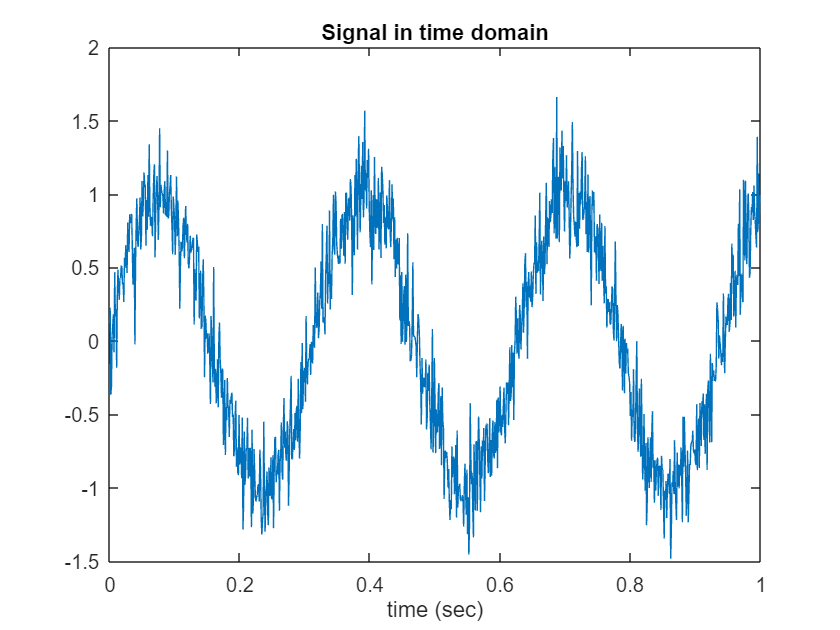

% plot signal
figure
t = (0:length(xs)-1)/fs;   % t = (0:n-1) * (1/fs);
plot(t,xs)  %--> xs not its fft!
title("Signal in time domain")
xlabel('time (sec)')

does your answer to the previous question match what you can observe from the plot of the signal in the time domain? 

A: kind of. There are 3 cycles in 1 second so that is 3Hz frequency so kind of makes sense

### 1d) Spectrum inperpretation

Look at the baseline of the amplitude spectrum. You will notice that the baseline is not zero. Instead, all remaining frequencies seem to have a small contribution to the signal. Were does this stem from? 

A: Maybe due to some noise?

### 1e) Filter the signal with a moving average filter of length 3 

b = [1/3, 1/3, 1/3] 

b =     0.3333    0.3333    0.3333


y = filter(b,1,xs);

### 1f) Plot the original and filtered signal in time domain in the same plot. What do you notice?

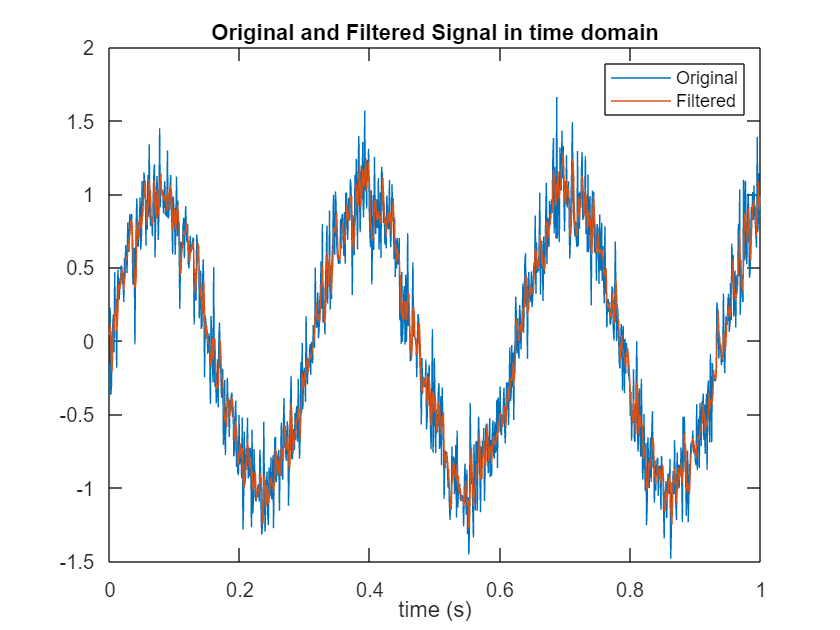

% figure;
% % plot command 1
% hold on;
% % plot command 2


figure%('Name', 'Q1 f) Orig and Filt. signal in time domain')
plot(t, xs)
hold on 
plot(t, y)
title('Original and Filtered Signal in time domain')
xlabel('time (s)')
legend('Original', 'Filtered')

A: The filtered signal definitely looks smoother but with some noise remaining

### 1g) Plot the amplitude spectra of the original and filtered signal in the same plot, what do you notice? Why?

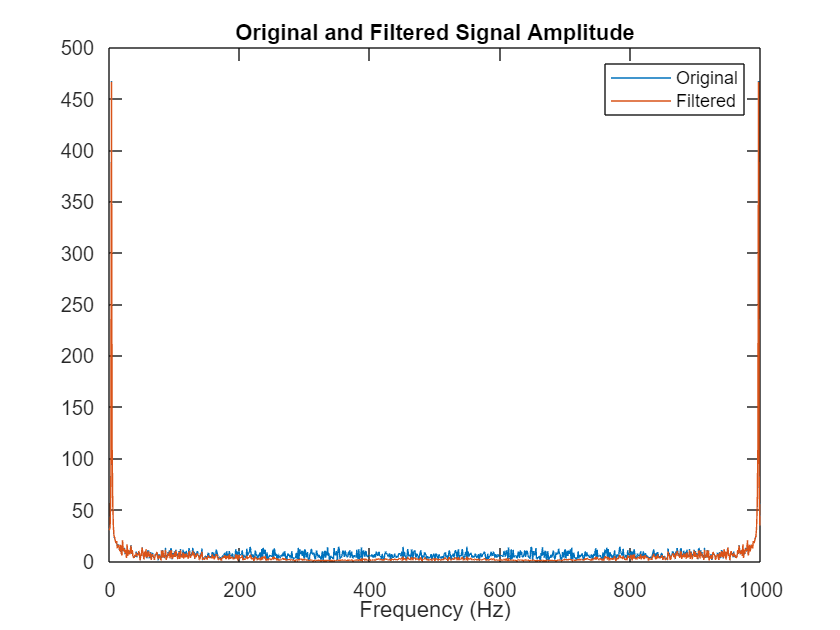

% figure;
% % plot command 1
% hold on;
% % plot command 2

Y = fft(y); %to have amplitude, need to have fft signal

figure('Name', 'Q1 f) Orig and Filt. signal amplitudes')
plot(f, abs(Xs))
hold on 
plot(f, abs(Y))
title('Original and Filtered Signal Amplitude')
xlabel('Frequency (Hz)')
legend('Original', 'Filtered')

A: The baseline of the filtered signal appears to be closer to 0. Actually,MA filter reduces the overall signal level so it leads to this shift. Also, the filter preserves the shapes of the amplitude spectrum. Therefore, the shape of the spectrumremains similar but the entire spectrum is shifted towards 0. 

The MA filter impacts differently the different frequencies. The lowest and highest (extremum) experience less influence compared to intermediate frequencies. This makes sense  with the filter' s limited frequency respeonse. ((GPT: As a type of low-pass filter, the moving average filter attenuates high frequencies more than low frequencies. Consequently, its effect is more pronounced on intermediate frequencies, causing a greater alteration in the spectrum, whereas the lowest and highest frequencies remain less affected.)

## Question 2

The filtered signal still looks noisy. Filter the signal with moving average filters of lengths 5, 10, 20, 30 and 50. What do you observe and why?

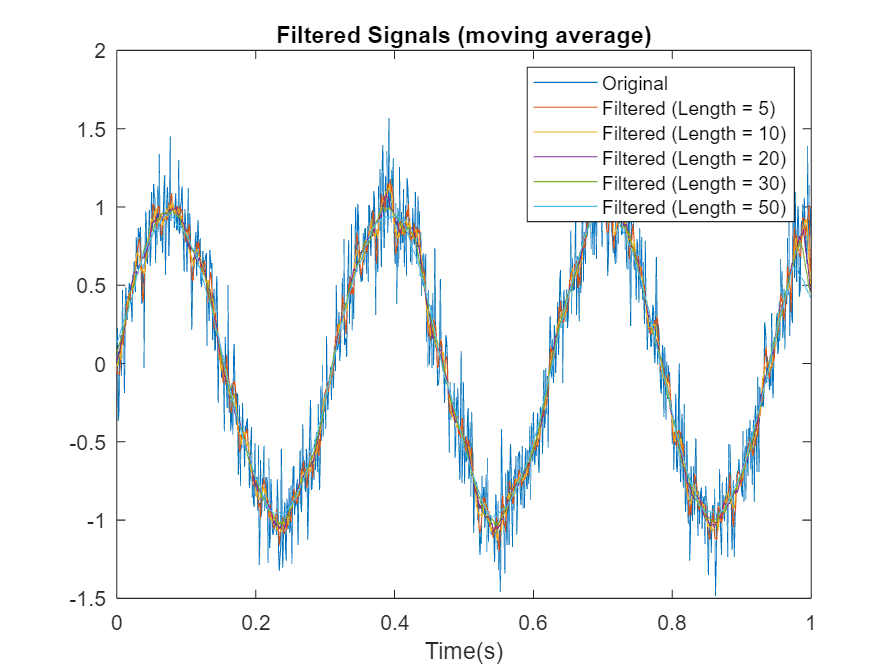

% your code here
filterOfLength = [5, 10, 20, 30, 50];

%first plot original signal:
figure%('Name', 'Q2 Moving Average Filter on Signal')
plot(t, xs, 'DisplayName', sprintf('Original'))
hold on

%now loop through all different filter lengths:

for i = 1 : length(filterOfLength)
    filter = filterOfLength(i);
    MAfilter = (1/filter) * ones(1, filter); %building moving average filter
    filterSignal = conv(xs, MAfilter, 'same'); %--> 'same' makes them the same length

    plot(t, filterSignal, 'DisplayName', sprintf('Filtered (Length = %d)', filter));
    legend('-DynamicLegend');
    legend('show');
end

xlabel('Time(s)')
title('Filtered Signals (moving average)')

For some reason, this is not what i should get so lets try an 'easier way' of doing...

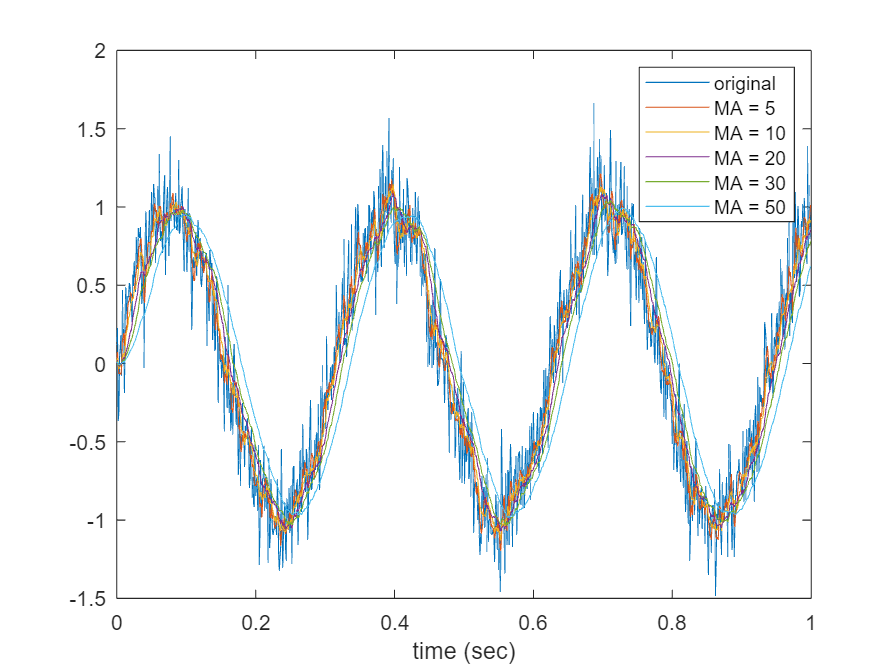

clear movingAVGfilter
y5 = movingAVGfilter(xs,5);
y10 = movingAVGfilter(xs,10);
y20 = movingAVGfilter(xs,20);
y30 = movingAVGfilter(xs,30);
y50 = movingAVGfilter(xs,50);

% plot all MovAvg filter and the original signal
figure
plot(t,xs)
hold on
plot(t,y5)
plot(t,y10)
plot(t,y20)
plot(t,y30)
plot(t,y50)
legend('original', 'MA = 5','MA = 10','MA = 20','MA = 30','MA = 50')
xlabel('time (sec)')

WHY DOES IT WORK NOW AND NOT BEFORE?? looks like notworking under for loop

## Question 3

clear
load data.mat
fs=102.4

fs = 102.4000

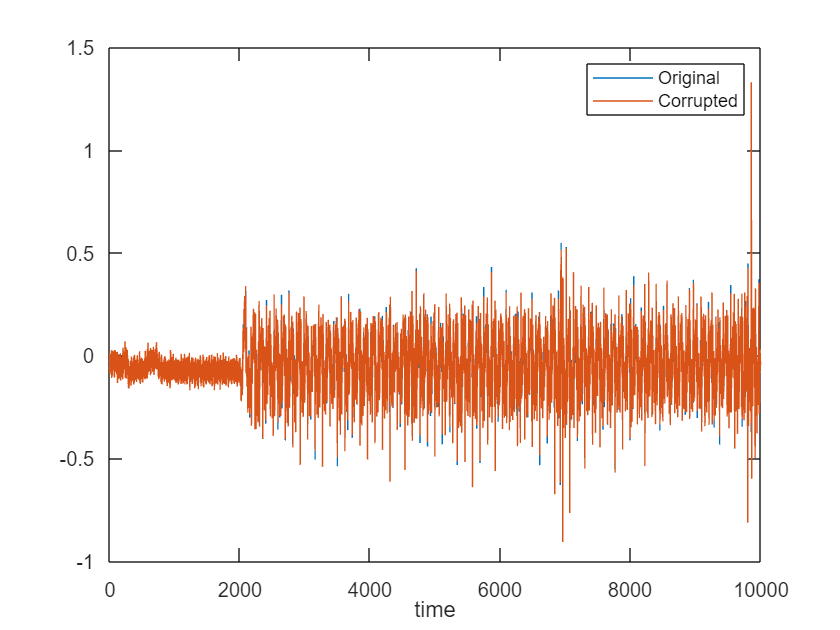

t = (0:length(data)-1)/fs;

%plot original and corrupted signal
figure%('Name', 'Original and corrupted signal')
plot(data,'DisplayName' ,'Original')
hold on
plot(d1,'DisplayName', 'Corrupted')
xlabel time
legend('-DynamicLegend')

### 3a) Calculate where the 50Hz and -50Hz frequencies are located in the (complex) z-domain 						

nf = 50 %noise frequency

nf = 50

z1 = exp(1i * 2 * pi * nf / fs);%50Hz
z2 = exp(-1i * 2 * pi * nf / fs);%-50Hz

### 3b) Place a zero at each of these locations

b = poly([z1, z2]);% polynomial with roots at z1 and z1
disp('Coefficients (b):');

Coefficients (b):


disp(b);

    1.0000    1.9946    1.0000



### 3c) Find the poles

The poles are between z = 0 and the zeros. Make their magnitude 0.9 times the magnitude of the zeros, find the denominator polynomial in a similar fashion and call its coefficients a.

p1 = 0.9*z1;
p2 = 0.9*z2;

a = poly([p1, p2]); %denominator polynomial (coefficients)

### 3d) Inspect your filter with freqz

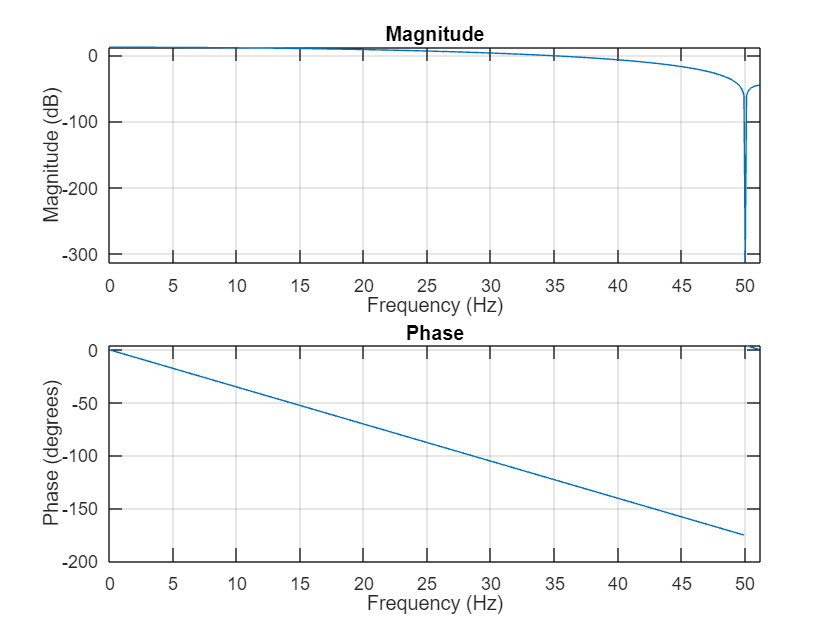

y = freqz(b,a,[],fs);

% FIR filter
figure
freqz(b,1,[],fs)

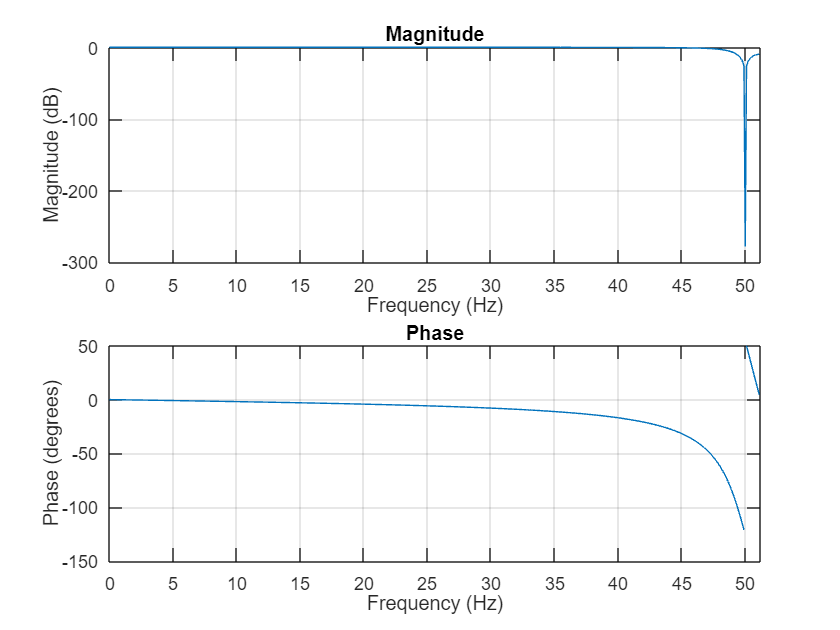

% IIR filter
figure
freqz(b,a,[],fs)

### 3e) Filter corrupted signal

Then use your filter to filter the corrupted signal d1. Try it by only using a FIR filter (the coefficients b only) and the using a IIR filter (the coefficients b and a).

% Filter corrupted signal d1 

%FIR -> b only
FIR = filter(b, 1, d1);

%IIR -> both b and a
IIR = filter(b, a, d1);

and compare your filtered signal, the corrupted signal and the original uncorrupted signal.  What are the differences between the IIR and FIR filters? Why?

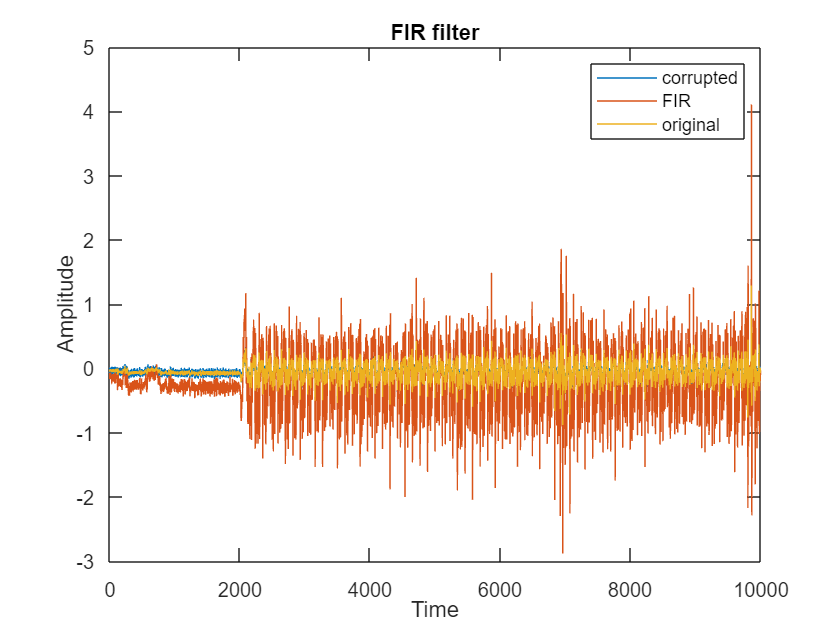

% plot corrupted, filtered and original data
figure;
% tiledlayout(1,2)
% 
% nexttile
% plot corrupted signal, FIR results and original signal
plot(d1)
hold on
plot(FIR)
plot(data)
hold off
xlabel('Time');
ylabel('Amplitude');
legend({'corrupted','FIR','original'});
title('FIR filter')

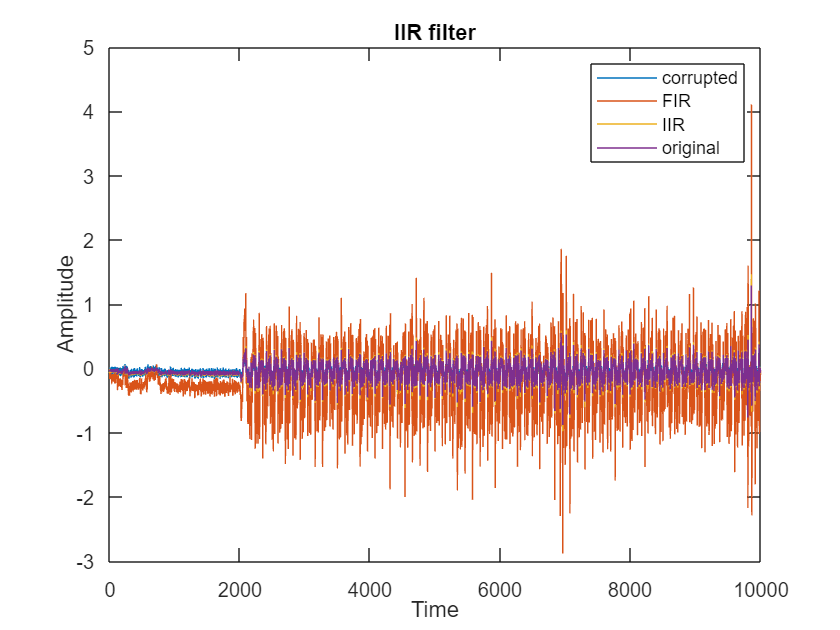


% nexttile
% plot corrupted signal, IIR results and original signal
figure
plot(d1)
hold on
plot(FIR)
plot(IIR)
plot(data)
hold off
xlabel('Time');
ylabel('Amplitude');
legend({'corrupted','FIR', 'IIR','original'});
title('IIR filter')

What are the differences? Why?

% ????????????????????????????????? TO DO

## Question 4

h=[0.25,0.5,0.25];

%Use the filter function to apply this filter to d1 from the previous question, yielding y1
y1 = filter(h, 1, d1);

### 4a) First, zero-pad d1 and h so that they have the same length:

n=length(h);
m=length(d1);
d1=[d1;zeros(n,1)];
h=[h';zeros(m,1)];

### 4b) Then, compute the FFT of d1 and h.

F=fft(d1);
H=fft(h);

### 4c) Compute:

Y2 = H.*F;

### 4d) Compute the FFT of y1

Y1 = fft(y1)% FFT of y1

Y1 = 1.0e+02 *

  -4.7199 + 0.0000i
  -0.2087 + 0.2761i
   0.1061 + 0.4272i
   0.0913 + 0.1904i
   0.1977 - 0.0431i
   0.0709 - 0.1224i
  -0.0752 + 0.0140i
  -0.1715 + 0.0034i
   0.0345 + 0.1553i
   0.0636 + 0.0227i


plot the absolute values of F, H, Y1, Y2 in a single figure. You might want to rescale H to make it visible. Try to interpret this plot!

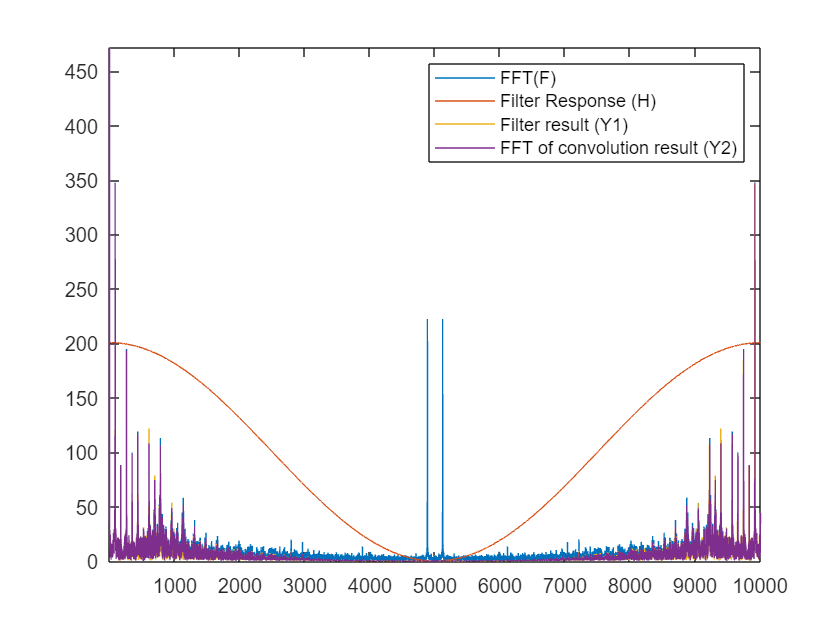

% figure;
% % Plot commands
% title('Frequency domain filtering (magnitudes)')
% legend({'FFT','Filter response','Filter result','FFT of convolution result'});
%-> computations for plots
%in order to rescale H to make it visible, here is what I should do:
%1. Calculate the maximum magnitude of F or Y1.
%2. Scale H by multiplying it by a factor that makes it visible in comparison.

% 1
max_magnitude = max([abs(F); abs(Y1)]);

%2
factor = 0.425;
Hscaled = factor*max_magnitude * H;

%plot
figure%('Name', 'Plot of absolute values of F, H, Y1 and Y2')
plot(abs(F), 'DisplayName','FFT(F)')
hold on
plot(abs(Hscaled), 'DisplayName', 'Filter Response (H)')
plot(abs(Y1), 'DisplayName','Filter result (Y1)')
plot(abs(Y2), 'DisplayName','FFT of convolution result (Y2)')

legend('-DynamicLegend')
axis tight

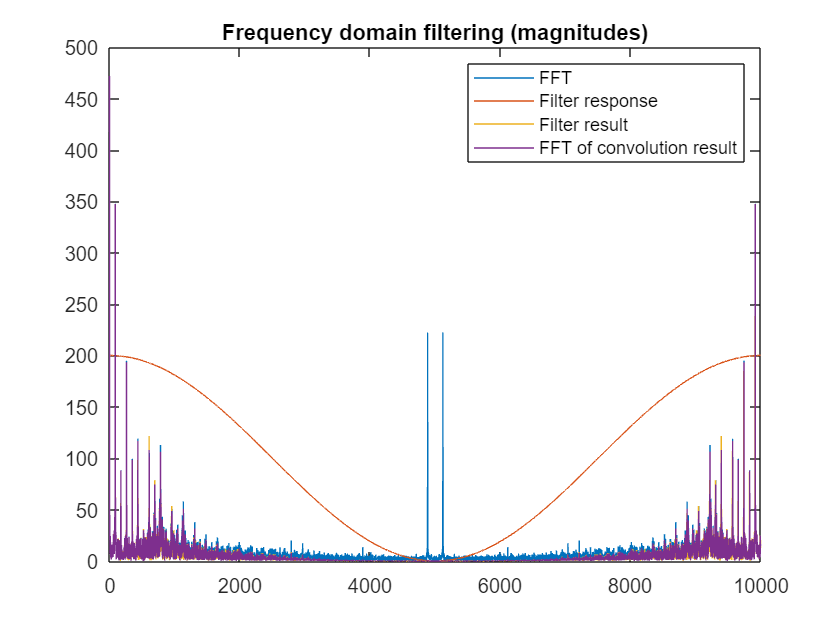

%could have done it in an easier way using rescale function
%H = rescale(logical(H),0,300)
figure
% Plot commands
plot(abs(F))
hold on
plot(rescale(abs(H),0,200))
plot(abs(Y1))
plot(abs(Y2))
xlim([0,10000])
title('Frequency domain filtering (magnitudes)')
legend({'FFT','Filter response','Filter result','FFT of convolution result'});

**EXPLANATION / INTERPRETATION OF GRAPH???**

blah?

### 4e) Check convolution theorem

Compute y2, the inverse Fourier transform of Y2: 

y2 = real(ifft(Y2));

and plot y1, y2, data, and d1 in a single figure.

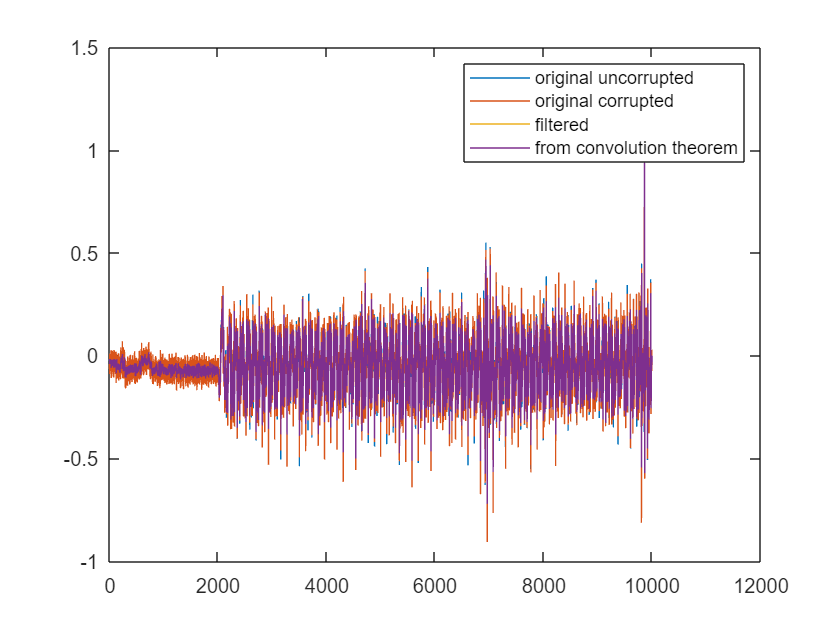

d1(end-2:end) = [];
y2(end-2:end) = [];

figure
plot(data)
hold on
plot(d1)
plot(y1)
plot(y2)
legend({'original uncorrupted','original corrupted','filtered','from convolution theorem'});

Does the convolution theorem check out?

check = isequal(y1, y2) %I know there are equql but soehow this does not work

check = logical
   0


% lets try another way
tolerance = 1e-6;

check = all(abs(y1 - y2) < tolerance);

if check
    disp('The convolution theorem holds: y1=~y2');
else
    disp('The convolution theorem does not hold: y1 =/= y2');
end

The convolution theorem holds: y1=~y2


A: The convolution theorem states that the convolution of two functions is equal to the inverse Fourier transform of the product of the Fourier transforms of the two functions. Indeed, when looking at our variables, we can see that the values of y1 (the convolution in the time domain) are equal to the values of y2 (multiplication in the frequency domain).

## Question 5

Read the help file of filter2 and try:

Im = [zeros(5,3),ones(5,2)]

Im =      0     0     0     1     1
     0     0     0     1     1
     0     0     0     1     1
     0     0     0     1     1
     0     0     0     1     1


h = ones(3,3)

h =      1     1     1
     1     1     1
     1     1     1


Now, Im is a (very small) 2D image and h is the filter kernel. The result of filtering Im with h is: 

g = filter2(h,Im)

g =      0     0     2     4     4
     0     0     3     6     6
     0     0     3     6     6
     0     0     3     6     6
     0     0     2     4     4


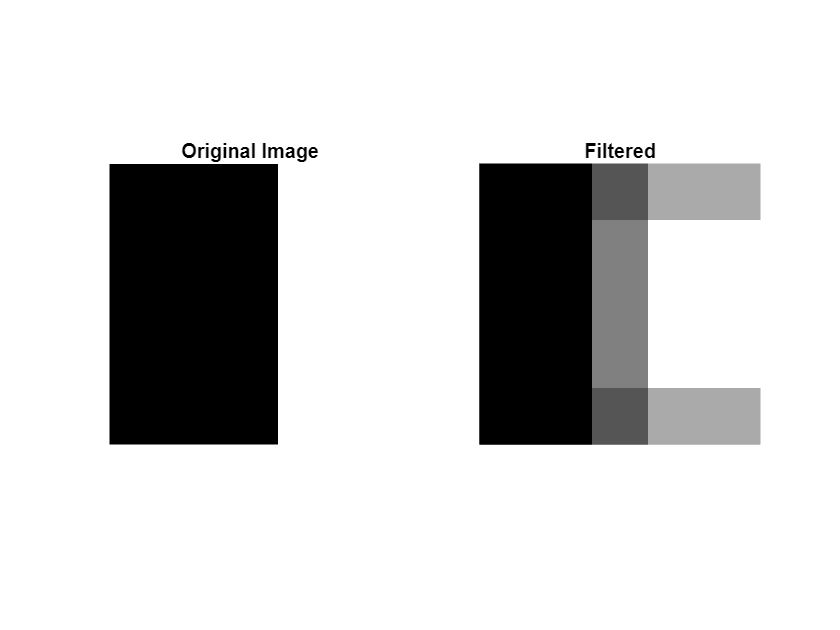

figure%('Name', 'Original Image and Filtered');
subplot(1, 2, 1), imshow(Im, []);
title('Original Image');
subplot(1, 2, 2), imshow(g, []);
title('Filtered');

If you want, you can verify the result by hand.

%to do


## Question 6

Load and display the image eight.tif. Add salt & pepper noise to the image by the use of the function noise.m, using 0.02 as noise density. Display the result. What this noise is characterized from?

Now you have to restore the original image:

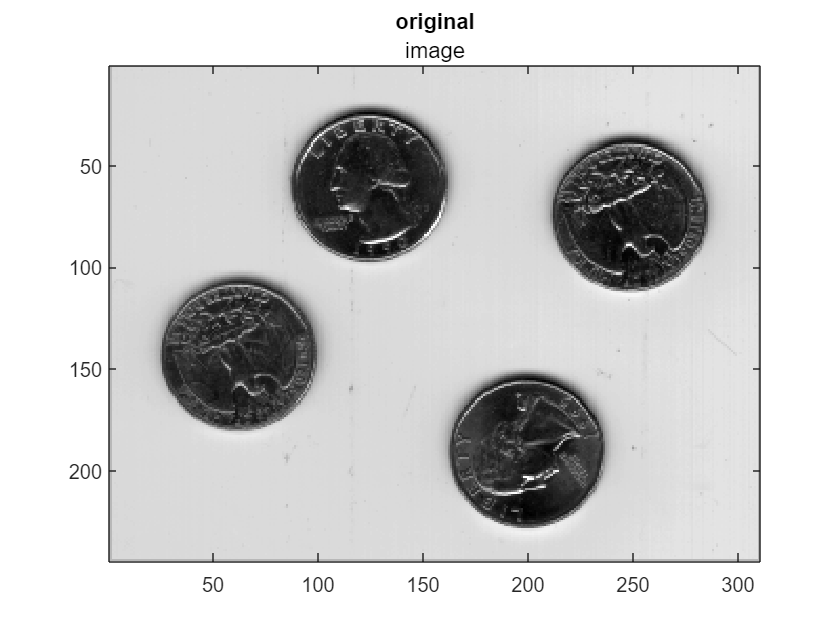

clear
%load image
[im, map] = imread('eight.tif');

%%viewing images
figure%('Name', 'Original Image and S&p noise (eight.tif)')
imagesc(im)
colormap gray
% colormap(map_eight)
title original image

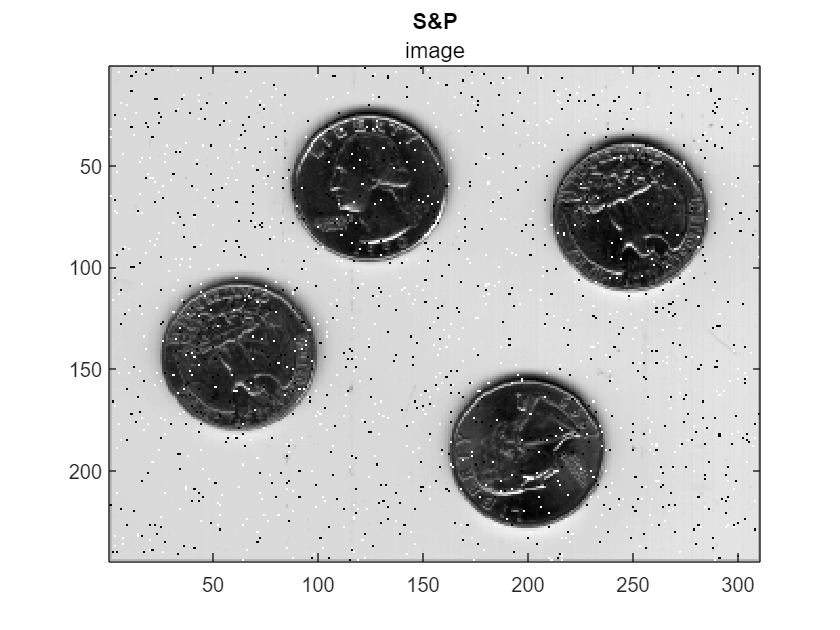

figure
noise_eight = noise(im, 'sp', 0.02);
imagesc(noise_eight)
colormap(gray)
title S&P image

### 6a) Create a (3 × 3), (5 × 5) and a (15 × 15) mean kernel

by doing for instance:

fsize3 = 3;
h3 = ones(fsize3)/fsize3^2;

fsize5 = 5;
h5 = ones(fsize5)/fsize5^2;

fsize15 = 15;
h15 = ones(fsize15)/fsize15^2;

### 6b) Filter the image using filter2

% filtering

g3 = filter2(h3,noise_eight);

g5 = filter2(h5,noise_eight);

g15 = filter2(h15,noise_eight);


### 6c) Look at the results

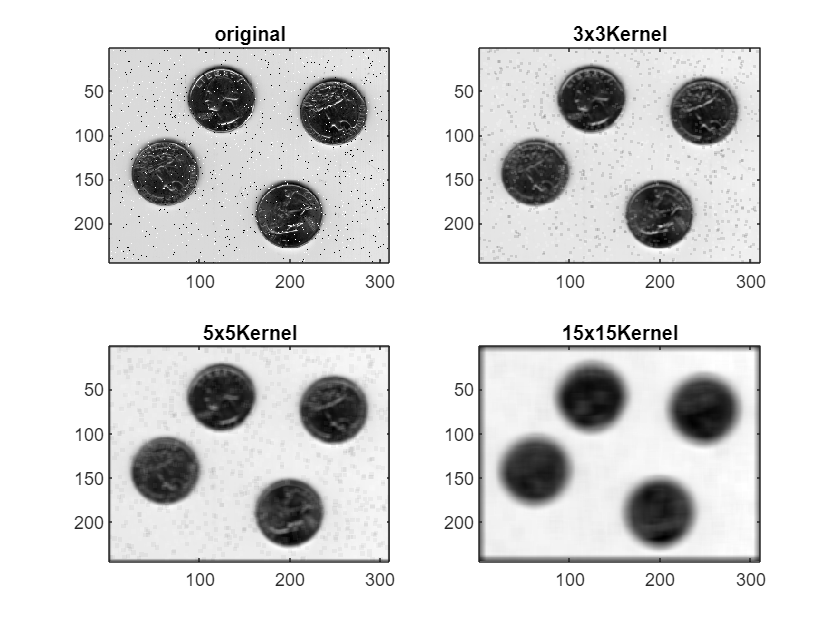

figure%('Name', 'S&P image filtered with different kernels')
subplot(221)
imagesc(noise_eight)
title original

subplot(222)
imagesc(g3)
title 3x3Kernel

subplot(223)
imagesc(g5)
title 5x5Kernel

subplot(224)
imagesc(g15)
title 15x15Kernel

colormap(gray)

What happens to the noise in the images? Is a mean filter suitable for removing salt & pepper noise?

A: REWRITE!!!!!

The salt & pepper noise does get removed but the quality of the image decreases by so much that the information in the image (the information of the coin = our signal) gets hard to read. It seems as if the noise is diminishing, but what really happens is that the noise just smeres out, but so does our information. 

The mean filter is not s suitable choice for removing this type of noise. A mean filter is a type of smoothing filter that works by replacing each pixel or sample in the signal with the mean or average value of the surrounding pixels or samples. It has the effect of smoothing out the signal and reducing the level of high-frequency content, but it does not do a good job of removing isolated high or low intensity pixels or samples, such as those that are characteristic of salt and pepper noise. In fact, using a mean filter to remove salt and pepper noise can often make the noise worse, as the mean filter will smooth out the signal and blur the edges of the high and low intensity pixels or samples, making them less distinct and more difficult to identify and remove.

A better approach would be using a median filter. Note though that you cannot implement such a filter using convolution as it is more algorithmic in nature. That means it is a non-linear filter.

## Question 7

Repeat question 6, but now by adding additive Gaussian noise to the original image with a 7% incidence.

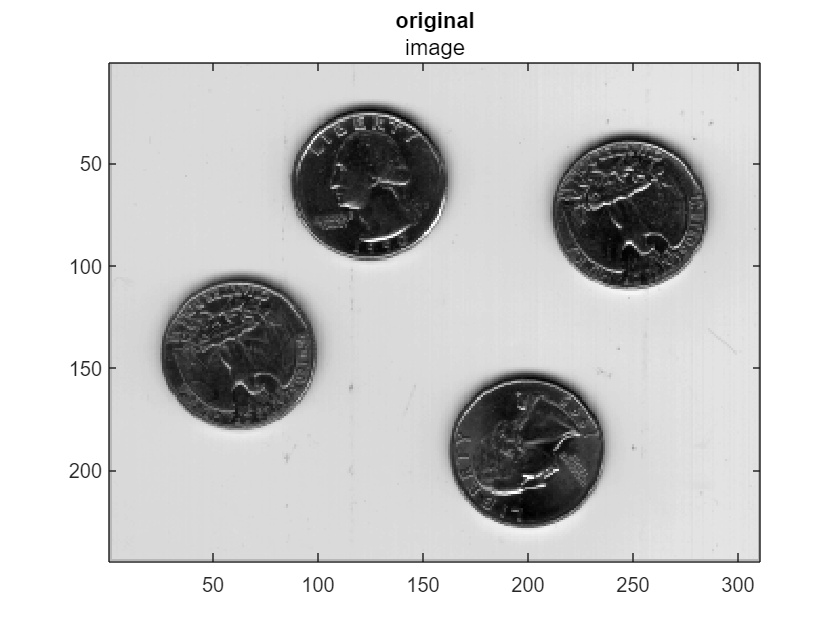

%load image
[eight, map_eight] = imread('eight.tif');

%%viewing images
figure%('Name', 'Original Image and AG noise (eight.tif)')
imagesc(eight)
colormap gray
title original image

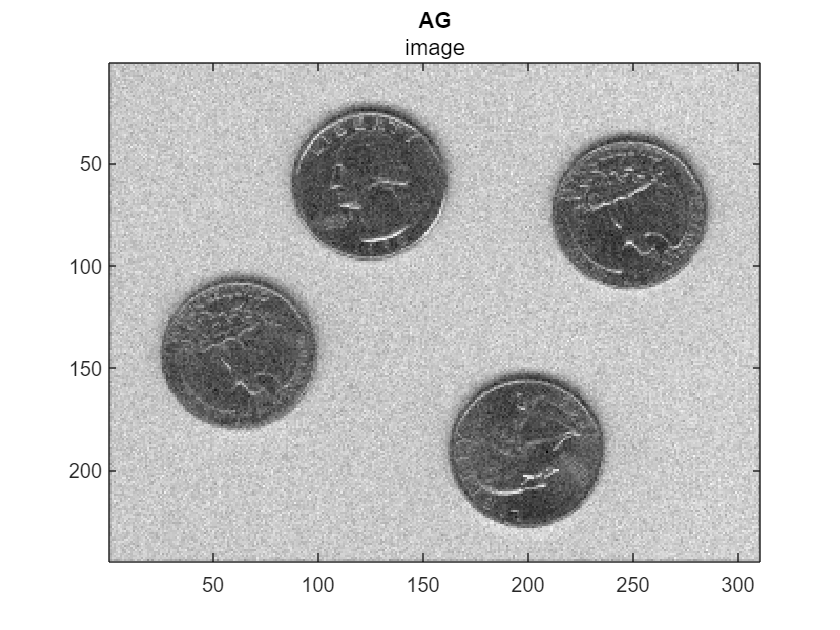


AGnoise_eight = noise(eight, 'ag', '7%');
figure
imagesc(AGnoise_eight)
colormap(gray)
title AG image

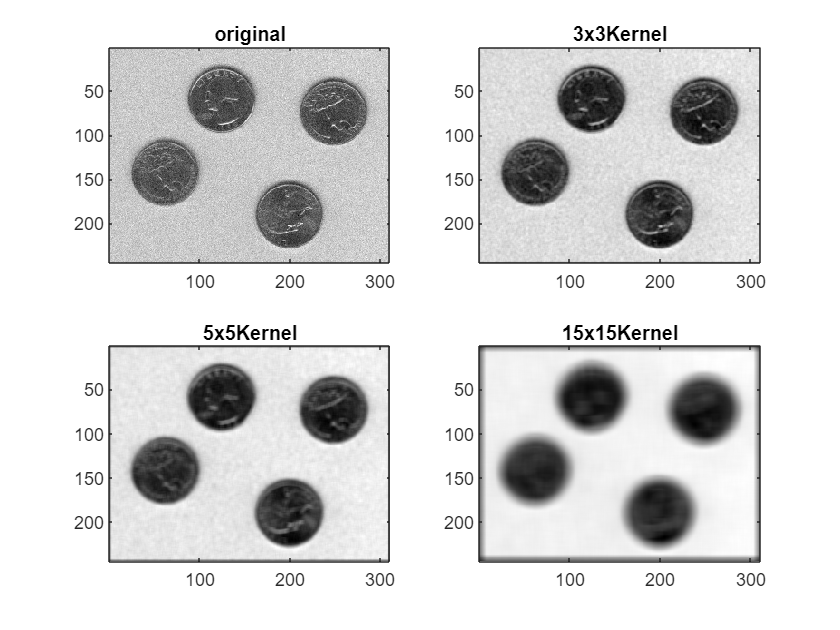



%a) Create a (3 × 3), (5 × 5) and a (15 × 15) mean kernel
fsize3 = 3;
h3 = ones(fsize3)/fsize3^2;

fsize5 = 5;
h5 = ones(fsize5)/fsize5^2;

fsize15 = 15;
h15 = ones(fsize15)/fsize15^2;

%b) Filter the image
%g= filter2(h,Im);

g3 = filter2(h3,AGnoise_eight);

g5 = filter2(h5,AGnoise_eight);

g15 = filter2(h15,AGnoise_eight);

%c) Plot everything and interpret the results

figure%('Name', 'AG image filtered with different kernels')
subplot(221)
imagesc(AGnoise_eight)
title original

subplot(222)
imagesc(g3)
title 3x3Kernel

subplot(223)
imagesc(g5)
title 5x5Kernel

subplot(224)
imagesc(g15)
title 15x15Kernel

colormap gray

What happens to the noise? What happens to the image?

**A:** The texture of the additive gaussian noise image is more grainy than before. There are several key differences between salt and pepper noise and additive Gaussian noise. The most important difference is the distribution of the noise: salt and pepper noise has a sparse distribution of high and low intensity pixels or samples, while additive Gaussian noise has a continuous distribution with a Gaussian or normal curve. This means that salt and pepper noise is more intermittent and difficult to remove than additive Gaussian noise, which is more evenly distributed and easier to reduce or eliminate.

We can see in the images that the gaussian noise represents a more realistic niose. In this case one needs to use a bigger filter to reduce the noise, but we can still observe texture in the background, while also losing further information on the coin. We can also see that we go from the orginial image witht the added noise from more midgray shades towards darker gray and brighter grays as the filter size increases. The contrast in the salt&pepper image is better in the orginal image.

In the following exercise we will go into further details of the filtering process, and look at the different boundary conditions available in the function filter2 (same, valid, and full):

(a) same means that the filtered image has the same dimensions as the original image.

(b) valid means that the filtered image is not affected by border problem.

(c) full means that the filtered image contained zero-padded borders. 

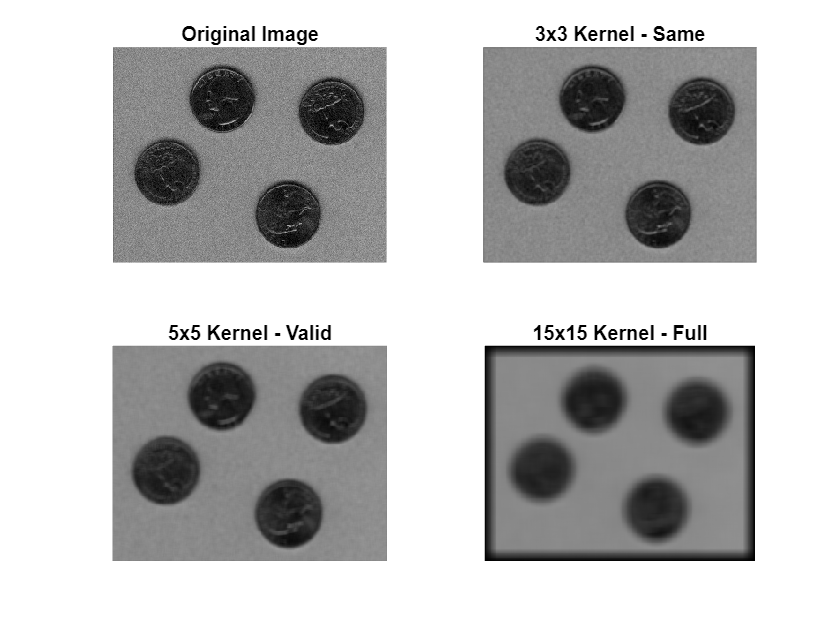

g3_same = filter2(h3, AGnoise_eight, 'same');
g5_valid = filter2(h5, AGnoise_eight, 'valid');
g15_full = filter2(h15, AGnoise_eight, 'full');

figure%('Name', 'AG Image Filtered with Different Kernels and Boundary Conditions')
subplot(221)
imshow(AGnoise_eight, gray)
title('Original Image')

subplot(222)
imshow(g3_same, gray)
title('3x3 Kernel - Same')

subplot(223)
imshow(g5_valid, gray)
title('5x5 Kernel - Valid')


subplot(224)
imshow(g15_full, gray)
title('15x15 Kernel - Full')

## Question 8

Read and display the image circle.bmp.

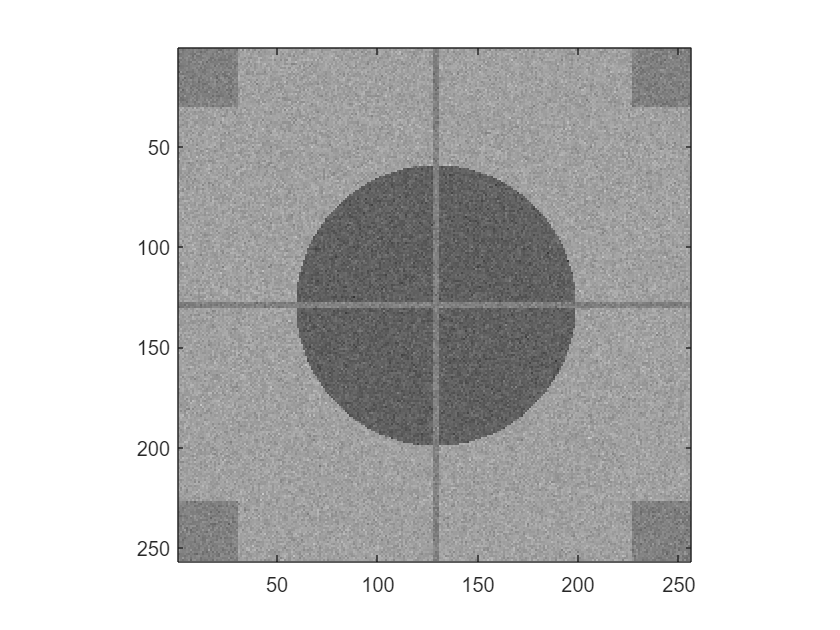

clear
im1 = imread('circle.bmp');
figure
image(im1)
colormap gray
axis image

Create a simple kernel for a mean filter by: 

fsize = 5;
h = ones(fsize)/fsize^2;

Use filter2 to apply the kernel to the image. Store the result into a variable called meanim1 and display both images in the same figure by using: 

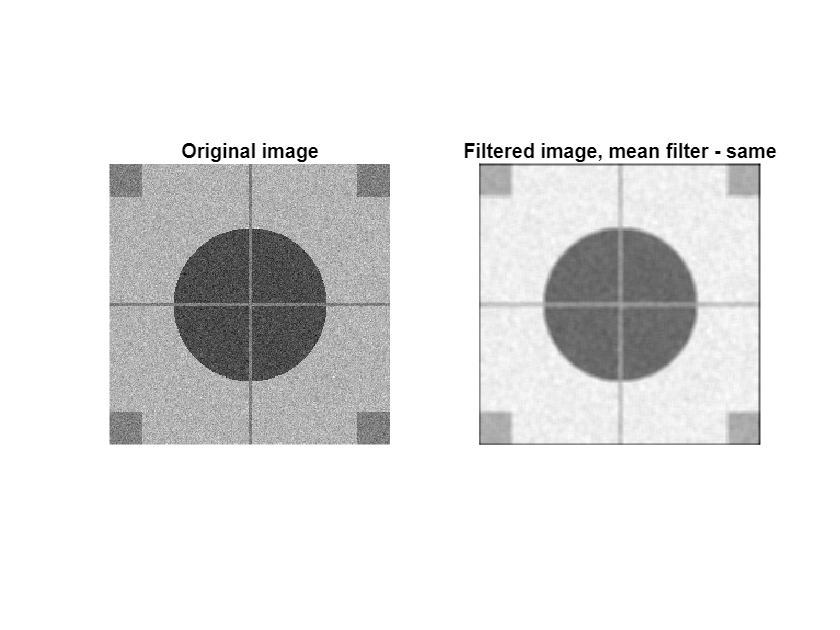

meanim1 = filter2(h,im1);               % this is the same a: meanim1_S = filter2(h,im1,'same');
figure
subplot(1,2,1);
imshow(im1,[]), colormap gray, axis image off;
title('Original image')
subplot(1,2,2);
imshow(meanim1,[]), colormap gray, axis image off;
title('Filtered image, mean filter - same')

Try filter2 with the three different options same, valid, and full. 

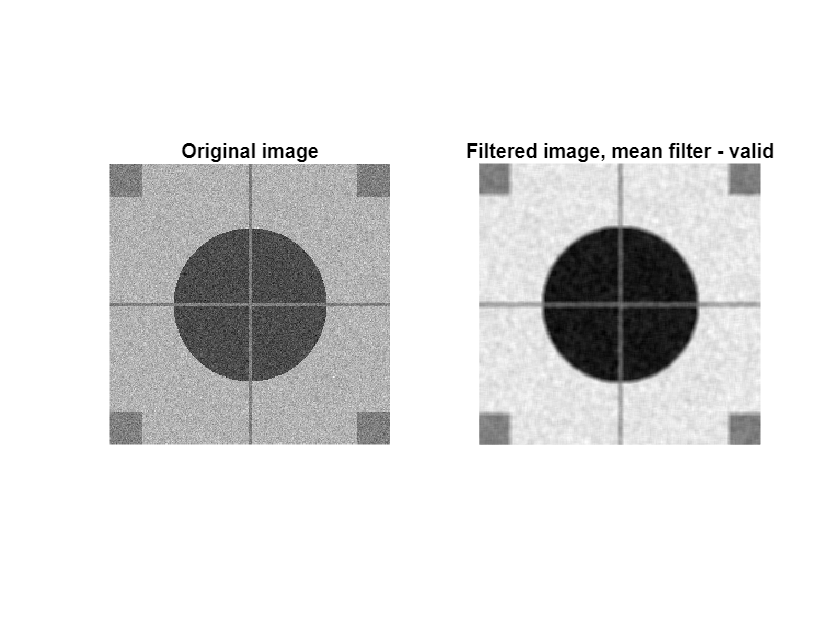

% meanim1_S = filter2(h,im1,'same');
meanim1_V = filter2(h,im1,'valid');
meanim1_F = filter2(h,im1,'full');

% % boundary: same
% figure
% subplot(1,2,1);
% imshow(im1,[]), colormap gray, axis image off;
% title('Original image')
% subplot(1,2,2);
% imshow(meanim1_S,[]), colormap gray, axis image off;
% title('Filtered image, mean filter - same')

% boundary: valid
figure
subplot(1,2,1);
imshow(im1,[]), colormap gray, axis image off;
title('Original image')
subplot(1,2,2);
imshow(meanim1_V,[]), colormap gray, axis image off;
title('Filtered image, mean filter - valid')

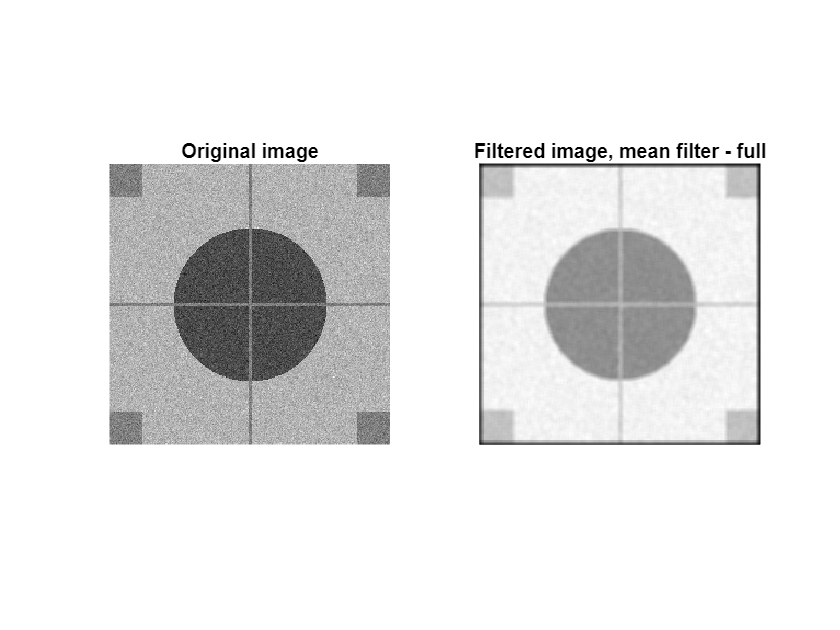

% boundary: full
figure
subplot(1,2,1);
imshow(im1,[]), colormap gray, axis image off;
title('Original image')
subplot(1,2,2);
imshow(meanim1_F,[]), colormap gray, axis image off;
title('Filtered image, mean filter - full')